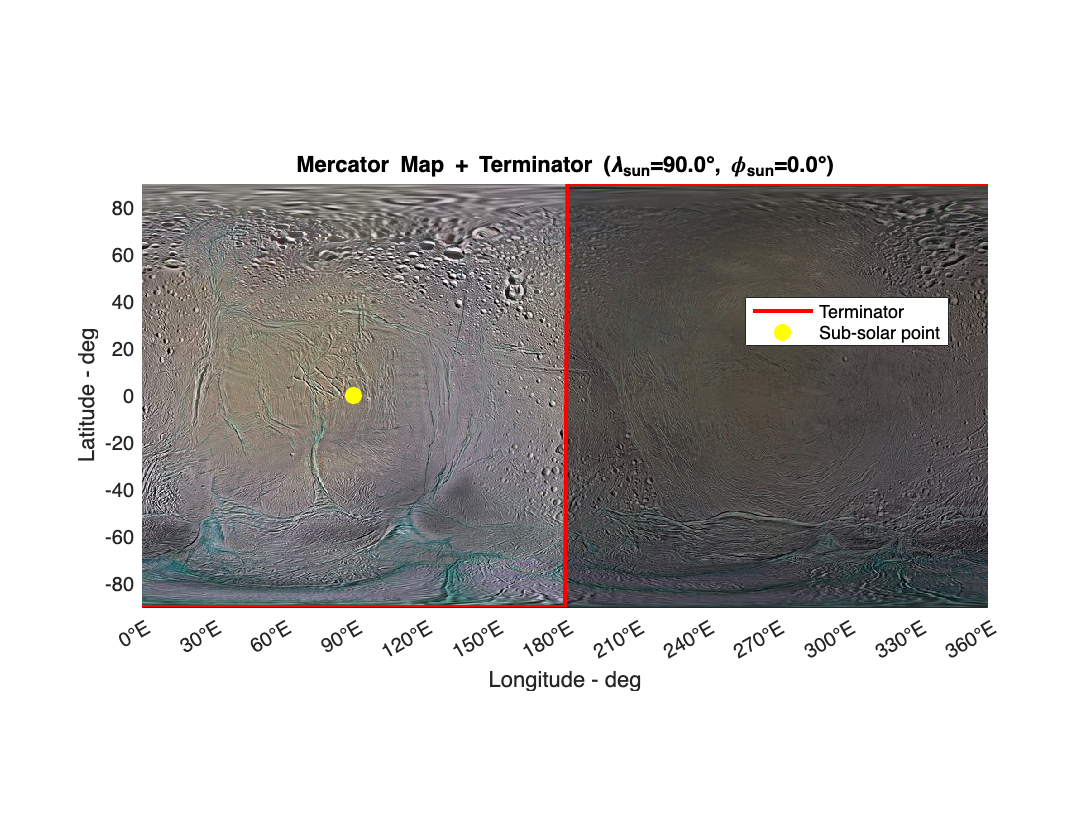

% Simple script to plot a planet texture (Mercator) and overlay the solar terminator
%
% Inputs:
%   lambda_sun = sub‐solar longitude [deg E positive, –180, +180]
%   phi_sun    = sub‐solar latitude  [deg N positive, –90, +90]


%% User inputs 
idCentral = 6;    % Saturn
idMoon    = 1;    % Enceladus

lambda_sun = 90;  % sub‐solar longitude [°E]
phi_sun    = 0;    % sub‐solar latitude [°N]
%% Draw the base Mercator texture
plotTextureLatLong(idMoon, idCentral);
hold on

%% Compute the terminator curve 
npts = 361;  % resolution: one point per degree  
lon = linspace(0, 360, npts);  
ha  = deg2rad(lon - lambda_sun);  % hour angle [rad]
lat_formula = atan( -cos(ha) ./ tan(deg2rad(phi_sun)) );  % terminator latitude [rad]
lat = rad2deg(lat_formula);  % back to degrees


%% Shade the nightside
% night is the side away from the sub‐solar latitude:
if phi_sun >= 0
    edgeLat = -90;  % extend patch down to South Pole
else
    edgeLat = +90;  % extend patch up   to North Pole
end

px = [lon, fliplr(lon)];
py = [lat, edgeLat*ones(1, npts)];
patch(px, py, 'k', 'FaceAlpha', 0.4, 'EdgeColor', 'none');

%% Draw the terminator line
hTerm = plot(lon, lat, 'r-', 'LineWidth', 2);

%% Highlight the sub‐solar point
% in this way works both if you input longitude [-180,180] or [0,360]
lon_sun = mod(lambda_sun + 360, 360);
lat_sun = phi_sun;
hSun   = plot(lon_sun, lat_sun, 'yo', ...
              'MarkerFaceColor', 'y', ...
              'MarkerSize', 8);

%% Extras
xlim([0 360])
legend([hTerm, hSun], {'Terminator','Sub‐solar point'}, 'Location','best')
title( sprintf('Mercator Map + Terminator (\\lambda_{sun}=%.1f°, \\phi_{sun}=%.1f°)', ...
                lambda_sun, phi_sun) )
grid on